# Week of July 11th 

#### By Bora Basyildiz

## I. Curve Evolution

    Reading over my notes for Computational Methods, I came across a realization. We are essentially doing an initial value problem but instead of points, we have curves. We start with our given C0, and then evolver it using our dC approximation (BSI, kB, or kB+). Now we have a much better course of action. First, we can use the existing IVP theoretical and computational framework to move forward confidently. But also, it leads to 'problem' arising. We can engineer our IVP solvers to be highly accuracy but very computationally intensive. Thus we have to fine tune our model to have the accuracy we desire, but also have feasible computational time. 

    For the IVP solvers, we have a few conditions. Our solver's must be *explicit*. This means that they will be less stable than implicit methods, but we are not really able to give implicit evolutions due to our framework. Also, we can store in evolved curves to enable multi-step methods. For now, I will use $\mathcal{O}(n^2)$ convergent methods, but if these do not suffice, we can use higher order methods as well. This leads to our initial step being a single step method using RK2, and then evolving our method through the multi-step AB2 (Runge-Kutta 2 and Adams-Bashforth 2). After doing this, we got better evolutions all across the board! Improving on this I implemented RK4 and AB4, and here are the results 

### kappa Binormal

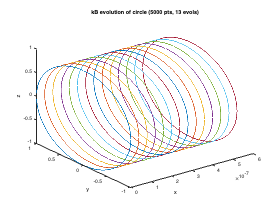

Curve_Evol('circle','kB',5000,13)

#### kappa Binormal Expansion

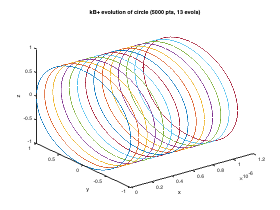

Curve_Evol('circle','kB+',5000,13)

#### Biot Savart Evol.

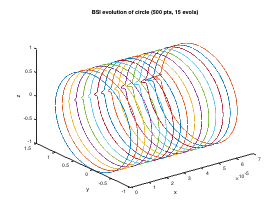

Curve_Evol('circle','BSI',500,15)

    Absurdly, BSI can use much less points than kB and kb+ BUT can evolve essentially to the same level. This, to me, indicates that within the kB code the Derivative function is diverging. I think the Derivative function has an error complexity of $\mathcal{O}(h^2)$ while the evolutions have $\mathcal{O}(h^4)$. Updating this Derivative function could be a next step in time evolution. 

    Also we see that the bump within BSI is still prevalent, which hopefully will be minimized with better numerical integration. I did not get to numerical integration this week, as my hands were full with the IVP evolution. 

## II. Functional Improvements 

    Many of the functions were improved to be cleaner and neater. Also, many of the used functions were given a *help* defition to assist with usable. See below

help Curve_Evol

 Curve_Evol(curve type, function type, # points, # evolutions) 
  DEF: Evolves a curve through a function. 
  Curve types: {'circle', 'ellipse', 'soliton', 'rough ring', 'ring soliton'}
  Function types: {'BSI', kB, kB+}



help Curve_Gen

 Curve_Gen(curve type, # points)
  DEF: Generates a specified curve 
  Curve types: {'circle', 'ellipse', 'soliton', 'rough ring', 'ring soliton'}



## III. Moving Forward

-     Since the evolutions are diverging around ~15 evolutions, an implicit Adam's-Moulton method may lead to higher levels of evolution. To use an implicity method, I have a few thoughts but I am open to other options. First, we can find our next $C_{n+1$ using a RK method, and then apply our derivtiave to find our ${dC}_{n+1}$, and then use this ${dC}_{n+1}$ in an AM implicit method. However, this seems to have a lot of overhead, and maybe there is a better way.

- Matlab's coding framework makes it impossible to hold arrays of arrays. For example I **cannot** hold something like $[C_0,C_1,...,C_n]$, which makes multi-step methods quite a pain. I instead just create a masive array and using slicing to get the respective $C$ value. (similar concept for $dC/dt$. 

- For the curve evolution, I needed a small value of $k$ to have a high amount of evolutions. This